# New Wireless Multiple Input Multiple Output Communication Technique with Enhance Security Using Precoder Matrices

warning off;
clc
clear

Nbps=1; 
M=2^Nbps;           % Modulation order=2/4/6 for QPSK/16QAM/64QAM
EbN0=0:5:40;        % EbN0, SNR
N_iter=5000;        % no of packets   % Number of iterations for each EbN0
Nframe=1;           % no. of sybmols in on % Number of symbols per frame

norms=[1 sqrt(2) 0 sqrt(10) 0 sqrt(42)];

%% Bob,Eve
PowerdB=[0 -8 -17 -21 -25]; % Channel tap power profile 'dB'
Delay=[0 3 5 6 8];          % Channel delay 'sample'
Power=10.^(PowerdB/10);     % Channel tap power profile 'linear scale'
Power=Power/(sum(Power));
Ntap=length(PowerdB);       % Chanel tap number
Lch=Delay(end)+1;           %Channel length
%%
Nfft=64;           % FFT size
Ng=16;             % Ng=0: Guard interval length
Nsym=Nfft+Ng;      % Symbol duration
Nused=Nfft ;

NgType=1;          % NgType=1/2 for cyclic prefix/zero padding
if NgType==1, nt='CP';  elseif NgType==2, nt='ZP';   end



for k=1:length(EbN0)
     BER_Rx1=0;
     BER_Rx2=0;
     BER_EVE_Rx1=0;
     BER_EVE_Rx2=0;
     
     TER_Rx1=0;
     TER_Rx2=0;
     TER_EVE_Rx1=0;
     TER_EVE_Rx2=0;
   
     bittot=0;
     
     for m=1:N_iter
      %h_ab  a=Tx b=Rx

Tx1 to to all Rx

      %Tx1 to Rx1 
      channel=(randn(1,Ntap)+1i*randn(1,Ntap)).*sqrt(Power/2);
       h11=zeros(1,Lch); 
       h11(Delay+1)=channel; % cir: channel impulse response
       h11Tx1=h11;
       H11=fft([h11Tx1 zeros(1,Nfft-Lch)]); % Channel frequency response
       
      %Tx1 to Rx2
       channel=(randn(1,Ntap)+1i*randn(1,Ntap)).*sqrt(Power/2);
       h21=zeros(1,Lch); 
       h21(Delay+1)=channel; % cir: channel impulse response
       h21Tx1=h21;
       H21=fft([h21Tx1 zeros(1,Nfft-Lch)]); % Channel frequency response
      
       %Tx1 to EVE
       channel=(randn(1,Ntap)+1i*randn(1,Ntap)).*sqrt(Power/2);
       hE1=zeros(1,Lch); 
       hE1(Delay+1)=channel; % cir: channel impulse response
       hETx1=hE1;
       H1E=fft([hETx1 zeros(1,Nfft-Lch)]); % Channel frequency response
       

Tx2 to all Rx


      %Tx2 to Rx1
       channel=(randn(1,Ntap)+1i*randn(1,Ntap)).*sqrt(Power/2);	
       h12=zeros(1,Lch); 
       h12(Delay+1)=channel; % cir: channel impulse response
       h12Tx2=h12;
       H12=fft([h12Tx2 zeros(1,Nfft-Lch)]); % Channel frequency response
      
      %Tx2 to Rx2
       channel=(randn(1,Ntap)+1i*randn(1,Ntap)).*sqrt(Power/2);	
       h22=zeros(1,Lch); 
       h22(Delay+1)=channel; % cir: channel impulse response
       h22Tx2=h22;
       H22=fft([h22Tx2 zeros(1,Nfft-Lch)]); % Channel frequency response
     
       %Tx2 to EVE
       channel=(randn(1,Ntap)+1i*randn(1,Ntap)).*sqrt(Power/2);	
       hE2=zeros(1,Lch); 
       hE2(Delay+1)=channel; % cir: channel impulse response
       hETx2=hE2;
       H2E=fft([hETx2 zeros(1,Nfft-Lch)]); % Channel frequency response

** Generate Signal for each antenna, modulate, and add CP**

      % X1 Data
      X1= randi([0,M-1], Nused*Nframe,1)'; % bit: integer vector (1)
      Xmod= qammod(X1,M,'gray')/norms(Nbps); 	
      
      % X2 Data
      X2= randi([0,M-1], Nused*Nframe,1)'; % bit: integer vector
      Xmod2= qammod(X2,M,'gray')/norms(Nbps);
           
      U1=Xmod;
      U2=Xmod2;    

**Precoder matrices**

       A = diag(H11);
       B = diag(H12);
       C = diag(H21);
       D = diag(H22);
       
       p1=-D/(C*B-D*A);
       p3=C/(C*B-D*A);

       p2=-B/(D*A-C*B);
       p4=A/(D*A-C*B);

**Superposition**

      %Antenna 1
      Tx1 = (1/sqrt(2))*U1*p1 + (1/sqrt(2))*U2*p2;
      %Antenna 2    
      Tx2 = (1/sqrt(2))*U1*p3 + (1/sqrt(2))*U2*p4;
      
      %% FOR PAPR
      x1np= ifft(U1);
      x_GI1np= guard_interval(Ng,Nfft,NgType,x1np);       
      x2np= ifft(U2);
      x_GI2np= guard_interval(Ng,Nfft,NgType,x2np);

**Antenna 1 (Tx1)**

        x1= ifft(Tx1)/norm(ifft(Tx1),2);  %% This is how i am normalizign it :step1
        norm(ifft(Tx1),2);
        x1WithGI= guard_interval(Ng,Nfft,NgType,x1);      

        y11Convolved=conv(x1WithGI,h11Tx1); %u1 r1
        y21Convolved=conv(x1WithGI,h21Tx1); %u1 r1
        y31Convolved=conv(x1WithGI,hETx1); %u1 r1
         
         %EbN0=20;
        snr = EbN0(k)+10*log10(Nbps*(Nused/Nfft)); % SNR vs. Eb/N0
         %snr=snr/2;
        EEs=sum(x1).^2/length(x1);    
        noise_mag  = sqrt(0.5*EEs*((10.^(-snr/10))));
        z1 = noise_mag*(randn(size(y11Convolved))+1i*randn(size(y11Convolved)));
        
        y11WithGI = norm(ifft(Tx1),2)*y11Convolved + z1/2; %% This is how i am normalizign : step2
        y21WithGI = norm(ifft(Tx1),2)*y21Convolved + z1/2; %% This is how i am normalizign : step2
        y31WithGI = norm(ifft(Tx1),2)*y31Convolved + z1/2; %% This is how i am normalizign : step2
         
        Y11= fft(remove_GI(Ng,Nsym,NgType,y11WithGI));
        Y21= fft(remove_GI(Ng,Nsym,NgType,y21WithGI));
        Y31= fft(remove_GI(Ng,Nsym,NgType,y31WithGI));

**Antenna 2 (Tx2)**

        x2= ifft(Tx2)/norm(ifft(Tx2),2);
        x2WithGI= guard_interval(Ng,Nfft,NgType,x2);       
        y12Convolved=conv(x2WithGI,h12Tx2); %u1 r2
        y22Convolved=conv(x2WithGI,h22Tx2); %u1 r2
        y32Convolved=conv(x2WithGI,hETx2);  %u1 r2
        
        % %%%%%%% FOR PAPR %%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
         
         if k==1
         PAPRtx1(1,m)=max((abs(x1WithGI)).^2)/mean((abs(x1WithGI)).^2);
         PAPRtx2(1,m)=max((abs(x2WithGI)).^2)/mean((abs(x2WithGI)).^2);
         PAPRtx3(1,m)=max((abs(x_GI1np)).^2)/mean((abs(x_GI1np)).^2);
         PAPRtx4(1,m)=max((abs(x_GI2np)).^2)/mean((abs(x_GI2np)).^2);
         %pause();
         end
         
         % %%%%%%% FOR PAPR %%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
  
        EEs=sum(x2).^2/length(x2);    
        noise_mag  = sqrt(0.5*EEs*((10.^(-snr/10)))); 
        z2 = noise_mag*(randn(size(y12Convolved))+1i*randn(size(y12Convolved)));
        
        
        
        y11WithGI = norm(ifft(Tx1),2)*y11Convolved + z1/2; %% This is how i am normalizign : step2
        y21WithGI = norm(ifft(Tx1),2)*y21Convolved + z2/2; %% This is how i am normalizign : step2
        y31WithGI = norm(ifft(Tx1),2)*y31Convolved + z1/2; %% This is how i am normalizign : step2
         
        Y11= fft(remove_GI(Ng,Nsym,NgType,y11WithGI));
        Y21= fft(remove_GI(Ng,Nsym,NgType,y21WithGI));
        Y31= fft(remove_GI(Ng,Nsym,NgType,y31WithGI));
        
        
        
        y12WithGI = norm(ifft(Tx2),2)* y12Convolved + z1/2; 
        y22WithGI = norm(ifft(Tx2),2)* y22Convolved + z2/2;
        y32WithGI = norm(ifft(Tx2),2)* y32Convolved;
 
        Y12= fft(remove_GI(Ng,Nsym,NgType,y12WithGI));
        Y22= fft(remove_GI(Ng,Nsym,NgType,y22WithGI));
        Y32= fft(remove_GI(Ng,Nsym,NgType,y32WithGI));
        

**No MRC**    

        YRx1= Y11'+Y12';
        YRx2= Y21'+Y22';
        YRxEVE= Y31'+Y32';

**Demodulation**

        Rx1=qamdemod(YRx1*norms(Nbps),M,'gray');
        Rx2=qamdemod(YRx2*norms(Nbps),M,'gray');
        RxEVE=qamdemod(YRxEVE*norms(Nbps),M,'gray');

        %% BER 
        BER_Rx1= BER_Rx1+sum(sum(de2bi(Rx1,Nbps)~=de2bi(X1,Nbps)));
        BER_Rx2= BER_Rx2+sum(sum(de2bi(Rx2,Nbps)~=de2bi(X2,Nbps)));
        BER_EVE_Rx1= BER_EVE_Rx1+sum(sum(de2bi(RxEVE,Nbps)~=de2bi(X1,Nbps)));
        BER_EVE_Rx2= BER_EVE_Rx2+sum(sum(de2bi(RxEVE,Nbps)~=de2bi(X2,Nbps)));
        
        %% Throughput
        TER_Rx1=TER_Rx1+(Nfft*Nbps)-sum(sum(de2bi(Rx1,Nbps)~=de2bi(X1,Nbps))); 
        TER_Rx2=TER_Rx2+(Nfft*Nbps)-sum(sum(de2bi(Rx2,Nbps)~=de2bi(X2,Nbps)));
        TER_EVE_Rx1=TER_EVE_Rx1+(Nfft*Nbps)-sum(sum(de2bi(RxEVE,Nbps)~=de2bi(X1,Nbps)));
        TER_EVE_Rx2=TER_EVE_Rx2+(Nfft*Nbps)-sum(sum(de2bi(RxEVE,Nbps)~=de2bi(X2,Nbps)));
        
        %% PAPR
        BERu1p(k,m)=sum(sum(de2bi(Rx1,Nbps)~=de2bi(X1,Nbps))); %for PER
        BERu2p(k,m)=sum(sum(de2bi(Rx2,Nbps)~=de2bi(X2,Nbps))); %for PER
        BERu1Ep(k,m)=sum(sum(de2bi(RxEVE,Nbps)~=de2bi(X1,Nbps)));
        BERu2Ep(k,m)=sum(sum(de2bi(RxEVE,Nbps)~=de2bi(X2,Nbps)));


        
        bittot=bittot+Nfft*Nbps;
        
     end
     
     %BER 
      BER_Tx1Rx1(k)=BER_Rx1/bittot;         % BER for TX1 TO RX1
      BER_Tx2Rx2(k)=BER_Rx2/bittot;         % BER for TX2 TO RX2
      BER_EVE_Tx1(k)=BER_EVE_Rx1/bittot;    % BER for EVE TO RX1
      BER_EVE_Tx2(k)=BER_EVE_Rx2/bittot;    % BER for EVE TO RX2
      
      %Thoruput
      resour=N_iter*Nfft;
      TER_Tx1Rx1(k)=TER_Rx1/(resour);
      TER_Tx2Rx2(k)=TER_Rx2/resour;
      TER_EVE_Tx1(k)=TER_EVE_Rx1/resour;
      TER_EVE_Tx2(k)=TER_EVE_Rx2/resour;
      
      %PER
      PERu11(k,:)=BERu1p(k,:)>0;
      PERu11p(k)=sum(PERu11(k,:)')/N_iter;
      
      PERu21(k,:)=BERu2p(k,:)>0;
      PERu21p(k)=sum(PERu21(k,:)')/N_iter;%Creating
      
      PBERu1E1(k,:)=BERu1Ep(k,:)>0;
      PBERu1E1p(k)=sum(PBERu1E1(k,:)')/N_iter;
      
      PBERu2E1(k,:)=BERu2Ep(k,:)>0;
      PBERu2E1p(k)=sum(PBERu2E1(k,:)')/N_iter;
end

## Plots

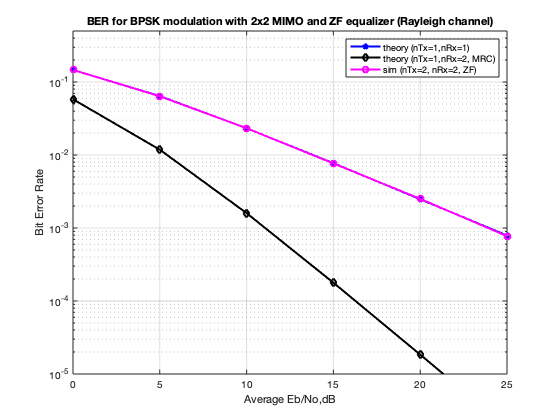

[Eb_N0_dB,theoryBer_nRx1,theoryBerMRC_nRx2,simBer]=MIMOwithZF;

%% BER
figure(1);


col=7;
semilogy(EbN0(1,1:col),BER_Tx1Rx1(1,1:col),'-pg','LineWidth',2); hold on
semilogy(EbN0(1,1:col),BER_Tx2Rx2(1,1:col),'--pb','LineWidth',2); hold on
semilogy(Eb_N0_dB(1,1:col),theoryBer_nRx1(1,1:col),'-pc','LineWidth',2);hold on
semilogy(Eb_N0_dB(1,1:col),simBer(1,1:col),'--pr','LineWidth',2);hold on

% semilogy(EbN0(1,1:col),BER_Tx1Rx1_DIV(1,1:col),'-pm','LineWidth',2); hold on
% semilogy(EbN0(1,1:col),BER_Tx2Rx2_DIV(1,1:col),'--pk','LineWidth',2); hold off

ax = gca;
xlabel('SNR (dB)','fontweight','bold','fontsize',10);
ax.XAxis.LineWidth = 2;
ax.XAxis.Color = 'r';
ylabel('Bit Error Rate (BER)','fontweight','bold','fontsize',10);
ax.YAxis.LineWidth = 2;
ax.YAxis.Color = 'b';
grid on;
legend('Rx1', 'Rx2', 'theory (nTx=1,nRx=1)', 'sim (nTx=2, nRx=2, ZF)','Rx1 \w Div', 'Rx2 \w Div','fontweight','bold');

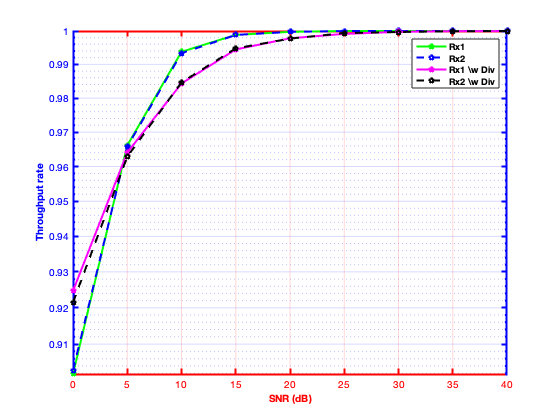

%% TER
figure(2);
semilogy(EbN0,TER_Tx1Rx1,'-pg','LineWidth',2);hold on;
semilogy(EbN0,TER_Tx2Rx2,'--pb','LineWidth',2);hold on;

semilogy(EbN0,TER_Tx1Rx1_DIV,'-pm','LineWidth',2);hold on;
semilogy(EbN0,TER_Tx2Rx2_DIV,'--pk','LineWidth',2);hold off;

ax = gca;
xlabel('SNR (dB)','fontweight','bold','fontsize',10);
ax.XAxis.LineWidth = 2;
ax.XAxis.Color = 'r';
ylabel('Throughput rate','fontweight','bold','fontsize',10);
ax.YAxis.LineWidth = 2;
ax.YAxis.Color = 'b';
grid on;
legend('Rx1','Rx2','Rx1 \w Div','Rx2 \w Div','fontweight','bold');

%%PER
figure(3);
semilogy(EbN0(1,1:col),PERu11p(1,1:col),'-pg','LineWidth',2); hold on;
semilogy(EbN0(1,1:col),PERu21p(1,1:col),'--pb','LineWidth',2);hold on;
semilogy(EbN0(1,1:col),PERu11p_DIV(1,1:col),'-pm','LineWidth',2); hold on;
semilogy(EbN0(1,1:col),PERu21p_DIV(1,1:col),'--pk','LineWidth',2);hold off;

ax = gca;
xlabel('SNR (dB)','fontweight','bold','fontsize',10);
ax.XAxis.LineWidth = 2;
ax.XAxis.Color = 'r';
ylabel('Packet Error Rate (PER)','fontweight','bold','fontsize',10);
ax.YAxis.LineWidth = 2;
ax.YAxis.Color = 'b';
grid on;
legend('Rx1','Rx2','Rx1 \w Div','Rx2 \w Div','fontweight','bold');


%%PAPR
PAPRtx1dB=10*log10(PAPRtx1); % in dB
[F1,X1] = ecdf(PAPRtx1dB); %CDF

PAPRtx2dB=10*log10(PAPRtx2); % in dB
[F2,X2] = ecdf(PAPRtx2dB); %CDF

PAPRtx3dB=10*log10(PAPRtx3); % in dB
[F3,X3] = ecdf(PAPRtx3dB); %CDF

PAPRtx4dB=10*log10(PAPRtx4); % in dB
[F4,X4] = ecdf(PAPRtx4dB); %CDF
figure(4)
semilogy(X1,1-F1,'-pb','LineWidth',2); hold on; % 1-F1 just to draw the CCDF
semilogy(X2,1-F2,'--pk','LineWidth',2); hold on;
semilogy(X3,1-F3,'-pm','LineWidth',2); hold on; % 1-F1 just to draw the CCDF
semilogy(X4,1-F4,'--pr','LineWidth',2); hold on;

semilogy(X1,1-F1_DIV,'-pb','LineWidth',2); hold on; % 1-F1 just to draw the CCDF
semilogy(X2,1-F2_DIV,'--py','LineWidth',2); hold off;

ax = gca;
xlabel('PAPR','fontweight','bold','fontsize',10);
ax.XAxis.LineWidth = 2;
ax.XAxis.Color = 'r';
ylabel('CCDF','fontweight','bold','fontsize',10);
ax.YAxis.LineWidth = 2;
ax.YAxis.Color = 'b';
grid on;
legend('Tx1-proposed','Tx2-proposed','Tx1-conventional','Tx2-conventional','Tx1-conventional','Tx2-conventional','fontweight','bold');